Polinomio de Lagranje

syms x
f = [3950 3870 3820 3900 3790 3751 3756];
t = [1 2 3 4 7 8 9];
C = [t',f']

C =            1        3950
           2        3870
           3        3820
           4        3900
           7        3790
           8        3751
           9        3756


n=length(C);
suma=0;
for i=1:n
L=1;
L1=1;
for j=1:n
if (i==j)
else
L=L*(x-C(j,1))/(C(i,1)-C(j,1));
end
end
suma=suma+C(i,2)*L;
end
%este es el polinomio de Taylor
Lagrange(x) = simplify(suma)

$$Lagrange(x) = -\frac{143\,x^{6}}{560}+\frac{13127\,x^{5}}{1680}-\frac{154163\,x^{4}}{1680}+\frac{173305\,x^{3}}{336}-\frac{148261\,x^{2}}{105}+\frac{712247\,x}{420}+\frac{16173}{5}$$

Lagrange(5)

$$ans = \frac{19813}{5}$$

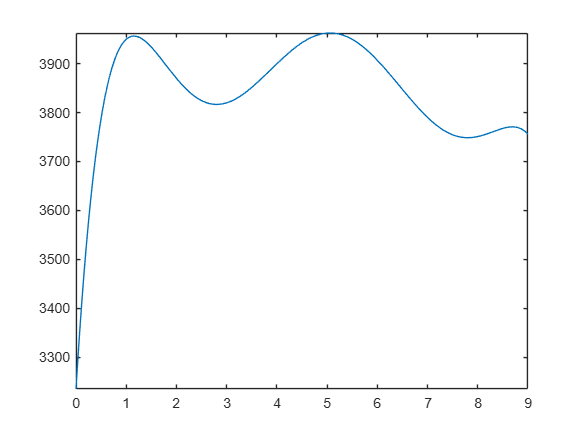

grid on
fplot(Lagrange)
xlim([0 9])